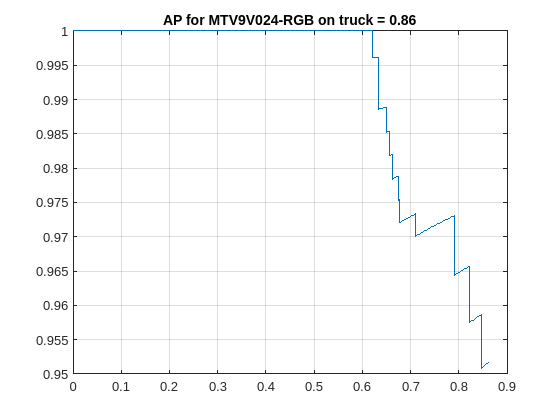

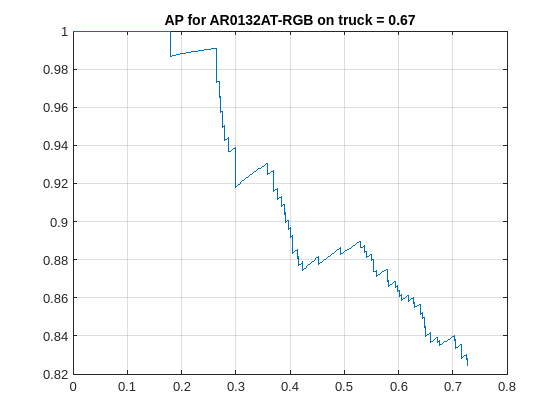

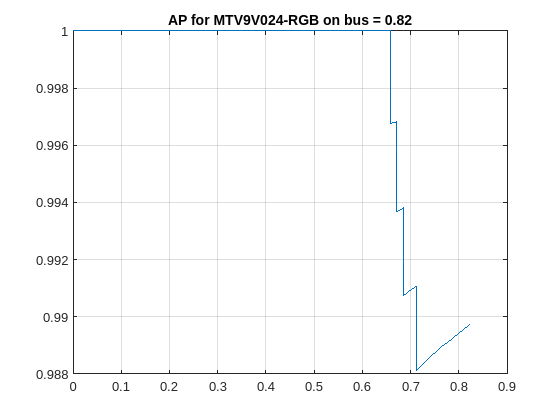

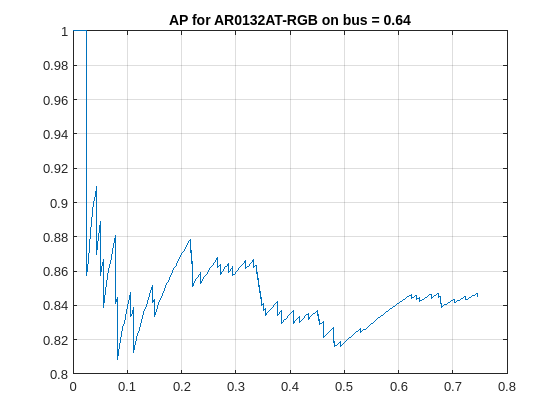

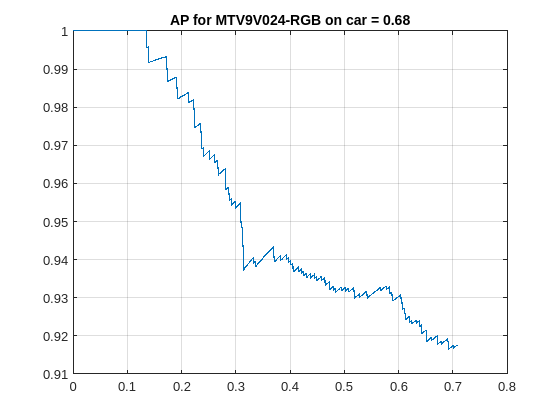

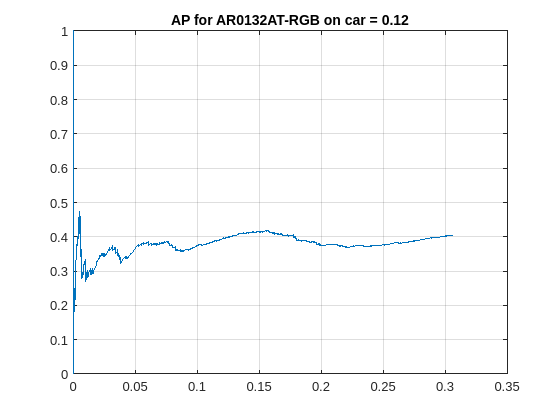

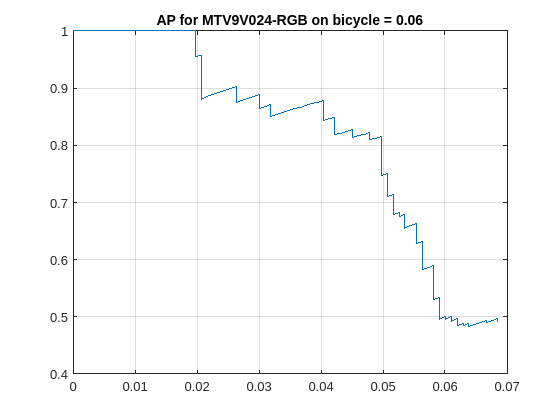

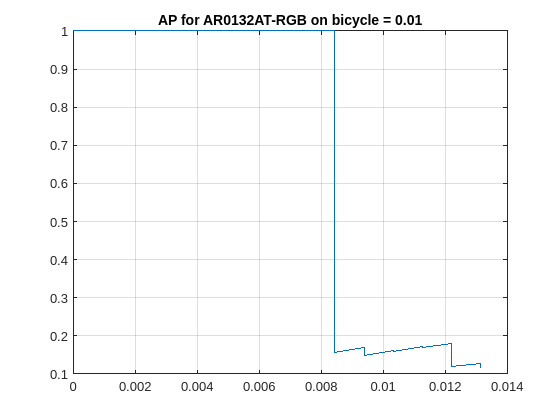

% Demonstration of how to use our database of images to
% evaluate the effectiveness of two sensors for detecting
% a specific class of closest object

% D. Cardinal, Stanford University, 2023

% First we get a collection of images from our database that
% have a specific class of object as the closest:

% Get a collection of images with a specific class of closest target
ourDB = isetdb();
dbTable = 'sensorImages';
filter = 'closestTarget.label';
targetClasses = {'truck', 'bus', 'car', 'bicycle' 'person'};

% Currently these are the two automotive sensors we have in our database
%sensorNames = {'MTV9V024-RGB'};
sensorNames = {'MTV9V024-RGB', 'AR0132AT-RGB'};

for jj = 1:numel(targetClasses)
    queryString = sprintf("{""closestTarget.label"": ""%s""}", targetClasses{jj});
    sensorImages = ourDB.docFind(dbTable, queryString);

    % Separate images by sensor
    perSensorImages = {};
    perSensorResults = {};

    for ii = 1:numel(sensorNames)
        perSensorIndex = arrayfun(@(x) matches(x.sensorname, sensorNames{ii}),sensorImages);
        perSensorImages{ii} = sensorImages(perSensorIndex); %#ok<*SAGROW>

        % prune for degugging
        [ap, precision, recall] = ol_apCompute(perSensorImages{ii}, 'class', targetClasses{jj});
        perSensorResults{ii} = {ap, precision, recall};

        figure;
        plot(recall, precision);
        grid on
        title(sprintf('AP for %s on %s = %.2f', sensorNames{ii}, targetClasses{jj}, ap))

    end
end